**Co**ntinuation of **S**olution **T**orus **A**pp**R**oximations

[Engineering Dynamics Group, Institute for Mechanics, University of Kassel, Germany](https://www.uni-kassel.de/maschinenbau/institute/mechanik/fachgebiete/technische-dynamik/startseite)

# Tutorial: Postprocessing Function `solget`

## Welcome to the CoSTAR Tutorials!

In this tutorial, we will look at the postprocessing functions `solget` and how to use it. `solget` is used to obtain solutions data, which can be further used for individual purposes, in different *solution spaces* without plotting.

Apart from `solget`, there are also the postprocessing methods `contplot` for creating continuation (bifurcation) diagrams and `solplot` for plotting individual solutions. These methods also return the plotted data points. To learn about `contplot` and `solplot`, please see the corresponding tutorials.

Of course, we need a solution computed by CoSTAR before we can use the postprocessing functions, so we start with a continuation in order to have a set of solutions at hand. After that, we will have a detailed look at `solget`.

## Computing solutions to work with

In this tutorial, we use the periodically forced *Duffing* oscillator $x^{\prime\prime} + 2Dx{\prime} + x + \kappa x^3 = g \cos (\eta \tau)$ as an example. The continuation parameter $\mu$ will be the excitation frequency $\eta$ and we will use the shooting method to approximate the solutions.

Before we can use CoSTAR, we need to add the main CoSTAR folder (and all subfolders) to MATLAB's search path. Assuming you are running this script within the *Tutorials* subfolder of CoSTAR, this is done by:

% addpath(genpath('..\'))           % genpath() generates a search path containing all subfolders

(Note: The command above is set as comment in order to prevent unwanted folders to be added to MATLAB's search path in case that the current path is not the *Tutorials* subfolder.)

Now we are set to perform a continuation of the periodically forced *Duffing* oscillator using the shooting method. The following code is taken from *Example_PS_SHM *and not explained any further at this point. If you are new to CoSTAR, it is advised to go through the corresponding example within the tutorial on periodic solutions approximated by the shooting method (see *Tutorial_PS_SHM*, chapter 1) before continuing with this tutorial.


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          4           0.0292105                           0.171              1
     1          8           3.649e-18       0.170911         1.42e-09              1

Equation solved. The sum of squared function values, r = 3.648999e-18, is less than
sqrt(options.FunctionTolerance) = 1.000000e-03. The relative norm of the gradient of r,
1.423941e-09, is less than options.OptimalityTolerance = 1.000000e-06.

-------------------------------------------------------
--------------- Initial solution found! ---------------
-------------------------------------------------------
Iter: 2 -- mu = 0.1100 -- stepwidth = 0.1000
Iter: 3 -- mu = 0.1642 -- stepwidth = 0.0500
Iter: 4 -- mu = 0.1729 -- stepwidth = 0.0250
Iter: 5 -- mu = 0.1903 -- stepwidth =

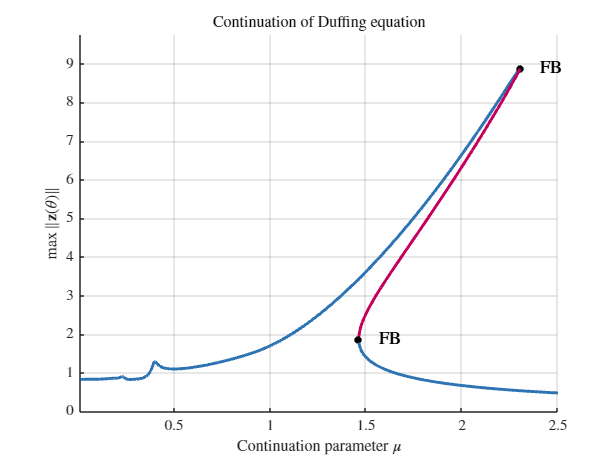

clear variables; clc; close all;                    % clear workspace; clear command window; close all figures

% Parameters
D = 0.05;     kappa = 0.3;     g = 1;               % Parameters needed for the Duffing differential equation
mu_limit = [0.01, 2.5];                             % Limits of the continuation        
eta0 = mu_limit(1);                                 % Value of continuation parameter at start of continuation
param = {kappa, D, eta0, g};                        % Parameter array
active_parameter = 3;                               % Location of continuation parameter within the array
IC = [1; 0];                                        % Initial condition (point in state space) for fsolve

% Functions
non_auto_freq = @(mu) mu;                           % Non-autonomous excitation frequency
Fcn =  @(t,z,param) duffing_ap(t,z,param);          % Right-hand side of dz/dtau = f(tau,z,kappa,D,eta,g)

% Options
options.system = costaropts('order',1,'dim',2,'rhs',Fcn,'param',param,'info','Continuation of Duffing equation');   % Properties of the system
options.opt_sol = costaropts('sol_type','periodic','approx_method','shooting','cont','on','stability','on', ...     % Properties of the solution
                             'non_auto_freq',non_auto_freq,'act_param',active_parameter);                           % Properties of the solution
options.opt_init = costaropts('ic',IC);                                                                             % Property for initial solution
options.opt_approx_method = costaropts('solver','ode45');                                                           % Properties of approximation method
options.opt_cont = costaropts('mu_limit',mu_limit);                                                                 % Properties for continuation

% Continuation
[S,DYN] = costar(options);                          % CoSTAR is called by costar(options)

Alright, now we have enough solutions to work with and we can begin with the actual tutorial on the postprocessing method `solget`.

# `solget`

The postprocessing function `solget` is used to obtain solution data in different *solution spaces*. In particular, three different solution spaces are available:

- ***Time*****:**              The solution data is returned with respect to time $t$

- ***Hypertime*****:**     The solution data is returned with respect to hypertime $\theta$ (periodic case) or $\mathbf\theta = \left(\theta_1,\;\theta_2\right)$ (quasi-periodic case)

- ***Frequency*****:**    The frequency content of a solution is returned

The solution space *trajectory*, which is available for the postprocessing method `solplot`, is not necessary here as a trajectory can easily be created based on a solution parametrised in time $t$.

In the following, we will focus on periodic (1D manifolds) and quasi-periodic (2D manifolds) solutions. Although equilibrium solutions (0D manifolds) could theoretically be returned in the available solution spaces as well, it does not really make sense since the resulting data would be trivial. That is why the use of `solget` is disabled for equilibrium solutions in CoSTAR. If you are interested in the solution data of an equilibrium solution, you can obtain it directly from the solution object `S` via `S.s`. The rows of `S.s` correspond to the state variables of the system, while the different solutions of a continuation are stored in the columns. The continuation parameter $\mu$ can be obtained by `S.mu`.

## General syntax

`solget` is used in the following way:

### **Input arguments**

- `DYN`**:** `DynamicalSystem` object returned by the `costar` function. Must correspond to `Solution` object `S`, which is also returned by the `costar` function.

- `solget_options`**:** Structure defining the necessary options. Must be created using the `costaropts` function. In case of any invalid entry, the CoSTAR *Gatekeeper* will throw an error.

### **Output arguments**

`solget` returns only one output argument `solget_output`, which is a *structure array*. Depending on the solution space in which the solution is returned, it contains four or five fields that are summarised in the table below. The corresponding field name is displayed in bold font at the top of each cell. The individual maximum possible field / array sizes are shown in brackets $[\;]$ at the bottom of each cell, where

- $n_{\text{S}}$ is the number of different solutions (in context of a continuation) to evaluate. The number corresponds to the field `'index'` via $n_{\text{S}}$ `=` `numel(options.index)` (further explanations of `'index'` can be found in the subsection **Optional fields** below).

- $r$ is the resolution, i.e. the number of data points of an evaluated solution along the underlying time or hypertime domain. $r$ can be set via the options field `'resolution'` (see subsection **Optional fields** below).

- $d$ is the dimension of the system.

- $d_{\text{req}}$ corresponds to the requested state variables of the system for each solution (in context of a continuation). It is determined by the value of the options field `'eval'` (see subsection **Mandatory fields** below). In case of `options.eval = 'all'`, $d_{\text{req}} = d$ since all state variables of a solution are returned. In case of `options.eval = 'euclidean'`, $d_{\text{req}} = 1$ since the Euclidean norm $\Vert \mathbf z \Vert$ of all state variables is returned. If `options.eval` is set as individual *function handle*, $d_{\text{req}}$ can be any number in the range of $1 \leq d_{\text{req}} \leq d$ and is equal to the size of the last array dimension of the *function handle*'s output, e.g. if the output has the size $[\,200 \, \times \; 3\,]$ then $d_{\text{req}}=3$.

The returned `options` structure is based on the input `options` structure, but it can change within `solget`. The input and output `options` structure may therefore differ.

The specific meaning of the evaluated solution data and of the returned frequency content depend on the requested evaluation of the solution, which is defined via the options field `'eval'`. For instance, the returned data can be the solution of the first state variable $z_1$ or the Euclidean norm $\Vert \mathbf z \Vert$ of all state variables. Further explanations of `'eval'` can be found in the subsection **Mandatory fields** below.

The individual array "structure" of the output fields can easily be understood by the table and explanation above.

- All array dimensions of size $n_{\text{S}}$ correspond to the different solutions (in context of a continuation) that are returned. If there is only one solution to return $(n_{\text{S}}=1)$, the corresponding array dimension is not present. For instance, the array size of `solget_output.time` is only $[\, r \, \times \; 1 \,]$ in this case.

- All array dimensions of size $r$ correspond to time $t$ or hypertime $\theta$ (periodic solutions / 1D manifolds). For evaluations in *quasi-periodic hypertime* solution space, there are two array dimensions $r_1$ and $r_2$ since the solutions are parametrised in hypertime coordinates $\theta_1$ and $\theta_2$. Naturally, $r_1$ corresponds to hypertime $\theta_1$ and $r_2$ corresponds to hypertime $\theta_2$. 

- For *frequency* solution space, the array dimensions of size $r\,/\,2$ correspond to the angular frequency $\omega$. Here, $r$ must be a positive even integer. Furthermore, the size of the second array dimension of `solget_output.angle` is always $d$ because, in contrast to the amplitudes, the specified option (or the defined *function handle*) of the options field `'eval'` is not applied to the phase angles.

- All array dimensions of size $d$ or $d_{\text{req}}$ correspond to the (requested) state variables of a system. These dimensions can contain the state variables themselves (e.g. in case of `options.eval = 'all'`, where $d_{\text{req}}=d$, or in case a *function handle* is defined appropriately, where $1 \leq d_{\text{req}} \leq d$`)` or they can contain the Euclidean norm $\Vert \mathbf z \Vert$ of all state variables (in case of `options.eval = 'euclidean'`, where $d_{\text{req}}=1$`)` or they contain the last array dimension of the defined *function handle's* output. In the latter case, $1 \leq d_{\text{req}} \leq d$ holds true as well (further explanations of the *function handle* can be found in the subsection **Mandatory fields** below).

As already stated above, the shown field / array sizes are the maximum possible sizes. For (and only for) the output field `solution_eval`, the array dimensions of size $r$, $r_1$, $r_2$ and $r\,/\,2$ also depend on the options field `options.eval` and their sizes may vary between 1 and each mentioned value. For instance, if `options.eval = @(z) max(z)` then the size of `solution_eval` is $[\, 1  \times \; d \times \; n_{\text{s}} \,]$ in all solution spaces except *quasi-periodic hypertime*. In the latter solution space, the size of `solution_eval` is $[\, 1 \times 1 \times \; d \times \; n_{\text{s}} \,]$ if `options.eval = @(z) max(z,[],[1 2])`. Further explanations of the possible output sizes can be found in the subsection **Mandatory fields** below.

After having discussed the input and output arguments of `solget`, we turn to the available options fields. It may be advisable to go through the section on the **Output arguments** again after reading the next section **Options**, as some explanations may then become clearer.

## Options

All settings for `solget` are defined via a structure array. This structure array must be created using the `costaropts` function, which is also used to create the general `options` structures for CoSTAR (see the example in the section **Computing solutions to work with **above). [*Reminder: The syntax of the input arguments of *`costaropts`* is equivalent to the MATLAB struct function, i.e. *`costaropts('fieldname1',fieldvalue1,...,'fieldnameN',fieldvalueN)`*.*] Similar to the general `options` structure, there are mandatory fields which always has to be definied. Apart from that, there are optional fields which can be set. Most of the optional fields have a default value. 

Let us have a look at the particular fields.

### **Mandatory fields**

So what does that mean? Let us call $x (\theta)$ the solution of the aforementioned *Duffing* equation and $x^{\prime}(\theta)$ its derivative. Since CoSTAR uses the state space representation of a differential equation in combination with the hypertime parametrisation approach, CoSTAR computes the state vectors $\textbf z_{\text{P}} (\theta) = [x(\theta) \;\;x^{\prime} (\theta) ]^\top$ (P: periodic) of a solution. When specifying `'euclidean'` for `'eval'`, mathematically speaking,$\Vert \mathbf z_{\text{P}}(\theta)\Vert$ (*hypertime* solution space) or $\Vert \mathbf z_{\text{P}}(t)\Vert$ (*time* solution space) is returned. In case of *frequency* solution space where a vector of (absolute) amplitudes $\mathbf F (\omega)$ is computed with respect to angular frequency $\omega$ (the $k$-th element of $\mathbf F (\omega)$ corresponds to the $k$-th state variable), $\Vert \mathbf F (\omega)\Vert$ is returned. When specifying `'all'` for `'zaxis'`, all state variables, i.e. all elements of $\textbf z_{\text{P}}$ ($x$ and $x^{\prime}$ in our example), are returned in the selected solution space. This is also true for *frequency* solution space where all $k$ elements of $\mathbf F (\omega)$ are returned.

For quasi-periodic solutions $\mathbf z_{\text{QP}} (\mathbf \theta) = \mathbf z_{\text{QP}} (\theta_1,\theta_2)$, the explanation above can be applied in an analogous manner. Please note that in case of *hypertime* solution space, the solution for each state variable is parametrised with respect to hypertime coordinates $\mathbf\theta = \left(\theta_1,\;\theta_2\right) \in [0, \; 2\pi]^2$ and can therefore be depicted as 2D hypertime surface.

After having discussed `'euclidean'` and `'all'`, let us turn to function handles, which can be used to define individual outputs. Due to different parametrisations of solutions, the input argument and therefore the required syntax changes depending on the solution space and the solution type.

As you can see, the input array type is a matrix for most cases. This is because *time*, *periodic hypertime*, *trajectory* and *frequency* solution space plots are all based on a parametrisation in time $t$, scalar hypertime $\theta$ or angular frequency $\omega$, i.e. these solution plots are based on a one-dimensional parametrisation. The only exception are quasi-periodic hypertime plots, where the solution is parametrised in two-dimensional hypertime $\mathbf\theta = \left(\theta_1,\;\theta_2\right)$. The maximum number of array dimensions of the output equals the number of array dimensions of the input argument, i.e. the output can be a 0D array up to a 3D array in *quasi-periodic hypertime* solution space and the output can be a 0D array up to a 2D array in any other solution space (see the examples in the table above). The maximum size for each array dimension can be taken from the table in subsection **Output arguments** above, where $n_{\text{S}}$ has to be omitted. E.g. the maximum size for each array dimension is reached in Example 1 and the minimal size for each output array dimension is reached in Example 2.

Next, we take a closer look at the optional fields available for `solget`.

### **Optional fields**

It is pointed out again that all of the optional fields do not have to be set. If a field is left out, its default value is used. 

When you just need a quick overview on the available fields of `solget` in the future, you can use the `costarhelp` feature. Typing 

in the command window will display the mandatory and optional fields, their allowed values and a short description for each available field.

Now we have discussed all available option structure fields of `solget`. To apply our newly acquired knowledge, we consider a few examples.

## Examples

The examples below are almost identical to the examples of the tutorial on the postprocessing method `solplot`. In contrast to that, however, no solutions are plotted.

### Solutions of all state variables

As a first example, we want to obtain the solution curves $x (\theta) = z_{\text{P},1} (\theta)$ and $x' (\theta) = z_{\text{P},2} (\theta)$ (i.e. the solution curves of all state variables in this case) of the $100^{\text{th}}$ solution $(\mu = \eta \approx 0.6)$ of our *Duffing* oscillator example. Thus, we set the options field `'space'` to `'hypertime'`, the field `'eval'` to `'all'` (the *function handles*` @(z)z `or` @(z)z(:,1:2) `could be used as well) and the field `'index'` to `100`. We do not define any other field and use their default values.

solget_options_1 = costaropts('space','hypertime','eval','all','index',100);    % @(z)z or @(z)z(:,1:2) could be used for 'eval' as well
solget_output_1  = S.solget(DYN,solget_options_1);

After `solget` was executed, the output structure `solget_output_1` consists of four fields: 

- `solution_eval:` As we selected the *hypertime* solution space, this field stores the solutions $x (\theta) = z_{\text{P},1} (\theta)$ and $x' (\theta) = z_{\text{P},2} (\theta)$ for $\theta \in [0, 2\pi]$. We only chose one solution at index `100`, which is why it is not a three-dimensional, but a two-dimensional array of size $[\, 200 \, \times \; 2 \, ]$. We did not specify a resolution, so the default value of $r=200$ is taken. Thus, the solution is returned at `200` evaluation points which are distributed equidistantly in the interval $[0, 2\pi]$. These solution values correspond to the first array dimension, while the second array dimension of size `2` coresponds to the state variables $z_{\text{P},1} (\theta)$ and $z_{\text{P},2} (\theta)$. To summarise this, the structure of the field `solution_eval` is         

`       solget_output_1.solution_eval = `$\left\lbrack \begin{array}{cc}
z_{\mathrm{P},1} \left(\theta =0\right) & z_{\mathrm{P},2} \left(\theta =0\right)\\
\vdots  & \vdots \\
z_{\mathrm{P},1} \left(\theta =\theta_i \right) & z_{\mathrm{P},2} \left(\theta =\theta_i \right)\\
\vdots  & \vdots \\
z_{\mathrm{P},1} \left(\theta =2\pi \right) & z_{\mathrm{P},1} \left(\theta =2\pi \right)
\end{array}\right\rbrack$     with     $\theta_i = i \cdot \Delta\theta = i \cdot \frac{2\pi}{r - 1} = i \cdot \frac{2\pi}{199}$     for all     $i \in \lbrace 0, 1,\ldots,198, 199 \rbrace$.

- `hypertime:` As its name suggests, the values of the hypertime $\theta$ at the evaluation points are stored in the field `hypertime`. With the above definition of $\theta_i$, the structure of this array is` solget_output_1.hypertime = `${\left\lbrack \begin{array}{ccccc}
0 & \cdots \; & \theta_i  & \cdots \; & 2\pi \;
\end{array}\right\rbrack }^{\top }$. When multiple $(n_{\text{s}})$ solutions are requested, it is a three-dimensional array of size $[\, r \, \times \; 1 \times \; n_{\text{s}} \,]$. However, there is no difference in the hypertime values of the different solutions since the fixed interval $\theta\in[0,\;2\pi]$ is applied to all requested solutions.

- `mu:` This field stores the value(s) of the continuation parameter $\mu$ of the returned solution(s) as a row vector. Therefore,` solget_output_1.mu` `=` $\mu_{100} \approx 0.603$ in this case. It is a scalar since we only evaluated one solution.

- `options:` This field stores the returned `options` structure of `solget`. Keep in mind that the input `options` structure `solget_options_1` and the output structure `solget_output_2` may be different. Analysing both of them in this example reveals that the field` options.resolution = 200 `was added to the `options` structure within `solget` since we did not specify the resolution.

### Solutions parametrised in time (including trajectories)

In the last example, we obtained the solution curves, which are parametrised in *hypertime* solution space with respect to hypertime $\theta$. Now we want to have a look at the solution with respect to time $t$ and get the data for $t \in [0, 25]$. We focus on the first state variable $z_{\text{P},1} (t) = x (t)$ of the solution at index `100` as well as of the solution at index `50` $(\mu = \eta \approx 0.39)$.

Therefore, we set the options field `'space'` to `'time'` and the field `'zaxis'` to` @(z)` `z(:,1)`. Furthermore, we define the field `'interval'` to obtain the solutions for the desired time interval and increase the value of the resolution from default `200` to $r=500$. Since the solutions at index `100` and index `50` are of interest, we set the field `'index'` to `[50,100]`.

solget_options_2 = costaropts('space','time','eval',@(z) z(:,1),'index',[50,100],'interval',[0,25],'resolution',500);
solget_output_2  = S.solget(DYN,solget_options_2);

Compared to the last example, the size of three out of four fields of the output structure `solget_output_2` has changed. 

- `solution_eval:` As we selected the *time* solution space and focus on the first state variable, the field `solution_eval` stores the solutions $x (t) = z_{\text{P},1} (t)$ for the defined interval $t \in [t_{\text{S}} \;\; t_{\text{E}}] = [0, 25]$ and for the specified resolution of $r=500$. Thus, $x (t) = z_{\text{P},1} (t)$ is returned at `500` evaluation points which are distributed equidistantly in the interval from $t_{\text{S}} = 0$ to $t_{\text{E}} = 25$. We chose the two solutions at index `50` and at index `100`, which is why `solution_eval` is a three-dimensional array of size $[\, 500 \, \times \; 1 \times \; 2 \,]$.  The values $x (t_i) = z_{\text{P},1} (t_i)$ of a solution correspond to the first two array dimensions, while the third array dimension of size 2 corresponds to the different solutions at indices `50` and `100`. The size of the second array dimension is only `1` since we requested only the first state variable via `options.eval`. To summarise this, the solution of index `50` $x_{50} (t)$ at the evaluation points is stored in the output structure by     

`       solget_output_2.solution_eval(:,1,1) = `${\left\lbrack \begin{array}{ccccc}
x_{50} \left(t=0\right) & \cdots \; & x_{50} \left(t=t_i \right) & \cdots \; & x_{50} \left(t=25\right)\;
\end{array}\right\rbrack }^{\top }$,     while the solution of index `100` $x_{100} (t)$ at the evaluation points is stored by

`       solget_output_2.solution_eval(:,1,2) = `${\left\lbrack \begin{array}{ccccc}
x_{100} \left(t=0\right) & \cdots \; & x_{100} \left(t=t_i \right) & \cdots \; & x_{100} \left(t=25\right)\;
\end{array}\right\rbrack }^{\top }$     with     $t_i = i \cdot \Delta t = i \cdot \frac{t_{\text{E}}-t_{\text{S}}}{r - 1} = i \cdot \frac{25}{499}$     for all     $i \in \lbrace 0, 1,\ldots,498, 499 \rbrace$.

- `time:` As its name suggests, the values of the time $t$ at the evaluation points are stored in the field `time`. In accordance with the structure of the field `solution_eval` and the above definition of $t_i$, the time evaluation points are stored in` solget_output_2.time(:,1,1) = solget_output_2.time(:,1,2) = `${\left\lbrack \begin{array}{ccccc}
0 & \cdots \; & t_i  & \cdots \; & 25
\end{array}\right\rbrack }^{\top }$. The second array dimension of `time` is always `1`, while the third array dimension corresponds to the different requested solutions. However, there is no difference in the time evaluation points of the different solutions since the (defined) evaluation interval is applied to all requested solutions.

- `mu:` This field stores the values of the continuation parameter $\mu$ of the returned solutions as a row vector. Therefore,` mu_val_solget_2` `=` $\left\lbrack \begin{array}{cc}
\mu_{50}  & \mu_{100} 
\end{array}\right\rbrack \approx \left\lbrack \begin{array}{cc}
0\ldotp 3914 & 0\ldotp 6030
\end{array}\right\rbrack \;$ in this case.

- `options:` This field stores the returned `options` structure of `solget`. Keep in mind that the input `options` structure `solget_options_2` and the output structure `solget_output_2` may be different.  Analysing both of them in this example reveals that they are actually identical in this case.

Apart from solutions with respect to time $t$, one perhaps want to obtain the trajectories of the solutions in state space. As a trajectory is also based on a parametrisation in time, we can almost use the code from the first part of this example to get all necessary trajectory data. However, the solution of the second state variable $x' (t) = z_{\text{P},2} (t)$ is still missing. Thus, we slightly adjust the definition of the field `'eval'` and set it to` @(z) z(:,1:2)`. Note that we could also set the field to `@(z)z` or to `'all'` since our exemplary *Duffing* oscillator system exhibits exactly two state variables. 

solget_options_3 = costaropts('space','time','eval',@(z) z(:,1:2),'index',[50,100],'interval',[0,25],'resolution',500);
solget_output_3  = S.solget(DYN,solget_options_3);

Notice that the size of `solget_output_3.solution_eval` is $[\, 500 \, \times \; 2 \times \; 2 \,]$ now, while the size of `solget_output_2.solution_eval` is only $[\, 500 \, \times \; 1 \times \; 2 \,]$. The fields `solget_output_3.time` and `solget_output_3.mu` did not change compared to their predecessors. The solutions $x_{50} (t)$ and ${x'}_{50} (t)$ at the evaluation points to obtain the trajectory can now be extracted from `solget_output_3` by` x_50 = solget_output_3.solution_eval(:,1,1) `and` x'_50 = solget_output_3.solution_eval(:,2,1)`, while the solutions $x_{100} (t)$ and ${x'}_{100} (t)$ at the evaluation points can be obtained by` x_100 = solget_output_3.solution_eval(:,1,2) `and` x'_100 = solget_output_3.solution_eval(:,2,2) `(also see the first example **Solutions of all state variables** above).

### Frequency content of a solution

As a third example, we want to compute the frequency content of the solutions at index `50` and at index `100`, so we set the options field `'space'` to `'frequency'`. Again, we focus on the first state variable $z_{\text{P},1} (t) = x (t)$ and thus set `'zaxis'` to` @(z)` `z(:,1)`. We do not set the field `'index'` to `[50,100]` this time because we treat each solution separately (the reason of why we do this should become clear after reading the next two paragraphs).

When computing the frequency content of a solution which was approximated using the *Finite Difference Method* or - as in this tutorial - the *Shooting Method,* a FFT (Fast-Fourier-Transformation) is carried out (in case of the *Fourier-Galerkin Method*, an explanation can be found at the end of this example). Here, it is important to note that for the (angular) frequency resolution $\Delta\omega$ of the resulting frequency domain (the difference between two consecutive frequency values $\omega_{k+1}-\omega_k$ in the resulting data), $\Delta\omega = 2\pi \cdot \frac{F_{\text{S}}}{r} = 2\pi \cdot \frac{r-1}{r} \cdot \frac{1}{\tau}$ holds. $F_{\text{S}} = \frac{1}{\Delta t} = \frac{r-1}{\tau}$ is the sampling frequency and $\tau$ the length / duration of the input signal, while $r$ is the number of sampling points, which is equal to the value of the options field `'resolution'`.  The input signal is a computed solution in *time* solution space for $t \in [t_{\text{S}} \;\; t_{\text{E}}]$, where $t_{\text{S}}$ and $t_{\text{E}}$ are set via the options field `'interval'`. Hence, for the duration $\tau$ it follows $\tau \; = \;\; t_{\text{E}} - t_{\text{S}}$` = options.interval(2) - options.interval(1)`. Therefore, we set the upper limit of `'interval'` to $100\, T$ ($T$: period of the solution) in order to achieve a good frequency solution $\Delta\omega$. However, this modification of `'interval'` drastically reduces the maximum frequency $\omega_{\text{max}}$ of the frequency domain (the maximum frequency that can be detected in the input signal), since $\omega_{\text{max}} = 2\pi \left( \frac{F_{\text{S}}}{2} - \frac{F_{\text{S}}}{r} \right) = \pi \cdot \frac{r-1}{\tau} \left(1 - \frac{2}{r} \right)$ is inversely proportional to $\tau$ as well. To compensate for that, we can easily increase the number of sampling points $r$ by defining a high value for the options field `'resolution'`. As the number of sampling points should be a power of $2$ for the FFT to be most efficient, we set `'resolution'` to $r= 2^{13} = 8192$.

Moreover, we should consider that the input signal of the FFT is assumed to be periodic. If we took exactly 100 periods of a periodic input signal $x(t)$, i.e. $t \in [t_{\text{S}} \;\; t_{\text{E}}] = [0, 100T]$, and continue it periodically, we would obtain the time series $\left\lbrack \begin{array}{cccccccc}
x\left(0\right) & \cdots  & x\left(100T\right) & x\left(0\right) & \cdots  & x\left(100T\right) & x\left(0\right) & \cdots 
\end{array}\right\rbrack$. This creates the problem that $x(0)$ follows $x(100T)$ directly, which does not make sense for periodic solutions in context of a time series. That is why the input signal of periodic solutions should only cover the time interval $t \in [t_{\text{S}} \;\; t_{\text{E}}] = [t_{\text{S}} \;\; (t_{\text{S}}+n \cdot T-\Delta t)]$ for the FFT to be most accurate, with $n \in \mathbb N$ and $\Delta t = t_{i+1} - t_i = n \cdot T \,/ \, r$ being the time step between two consecutive values of the time series. Thus, we first compute the periods $T_{50}$ and $T_{100}$ of the solutions at index `50` and at index `100`. The related angular frequencies can be taken from the `solution` object `S` via `S.freq(50)` and `S.freq(100)`. After that, we calculate the time steps $\Delta t_{50}$ and $\Delta t_{100}$ as well as the end times $t_{\text{E},50}$ and $t_{\text{E},100}$ of the intervals. Finally, we can call the `solplot` method and carry out a FFT of the solutions $x_{50} (t)$ and $x_{100} (t)$. It is done for each solution separately due to the different periods $T_{50}$ and $T_{100}$. CoSTAR then returns the absolute amplitudes $\vert \mathcal F_k (\omega) \vert$ as well as the phase angles $\text{arg} (\mathbf F_k (\omega) )$ for both of the two solutions $(k \in \lbrace{50, 100 \rbrace)$ with respect to the angular frequency $\omega$. The resulting frequency resolution $\Delta\omega_k$ can now be calculated from the sampling Frequency $F_{\text{S},k} = \frac{1}{\Delta t_k} = \frac{r}{n \cdot T_k} $ by $\Delta\omega_k = 2\pi \cdot \frac{F_{\text{S},k}}{r} = \frac{2\pi}{n \cdot T_k}$ and for the maximum frequency $\omega_{\text{max},k}$ of the frequency domain it follows $\omega_{\text{max},k} = 2\pi \left( \frac{F_{\text{S},k}}{2} - \frac{F_{\text{S},k}}{r} \right) = \pi \cdot F_{\text{S},k} - \Delta\omega_k = \frac{\pi}{n \cdot T_k} ( r - 2)$.

% Compute the end time of the intervals
res = 2^13;                                                                         % resolution
T_50 = 2*pi/S.freq(50);                 T_100 = 2*pi/S.freq(100);                   % periods of the solutions
Delta_t_50 = 100*T_50 / res;            Delta_t_100 = 100*T_100 / res;              % time steps between two consecutive points
int_end_50 = 100*T_50 - Delta_t_50;     int_end_100 = 100*T_100 - Delta_t_100;      % end time of the intervals
% Compute the frequency content of the solution x(t) at index 50
solget_options_4 = costaropts('space','frequency','eval',@(z) z(:,1),'index',50,'interval',[0 int_end_50],'resolution',res);
solget_output_4  = S.solget(DYN,solget_options_4);
% Compute the frequency content of the solution x(t) at index 100
solget_options_5 = costaropts('space','frequency','eval',@(z) z(:,1),'index',100,'interval',[0 int_end_100],'resolution',res);
solget_output_5  = S.solget(DYN,solget_options_5);

The two output structures `solget_output_X` (`X` $\in \lbrace 4, 5 \rbrace$) exhibit the following five fields:

- `amplitude:` As we selected the *frequency* solution space, the field `amplitude` stores the (absolute) amplitudes $\vert \mathcal F_k (\omega) \vert$ for the requested solution $x_k (t)$. We called `solget` to only evaluate the first state variable of one solution (index `50` or `100`), which is why `amplitude` is not a three-dimensional, but a one-dimensional array of size $[\, 4096\, \times \; 1 \,]$. Due to the FFT, the amplitude values $\vert \mathcal F_k (\omega_i) \vert$ are not returned at $r$, but at $r\,/\, 2$ frequency points $\omega_i$. These amplitude values correspond to the first array dimension, while the second array dimension corresponds to the state variables of the system. Here, its size is `1` since we only requested the first state variable. When multiple solutions are requested, a third array dimension of size `n_sol` appears, corresponding to the `n_sol` different solutions. To summarise this, the requested amplitude values are stored in the output structure by 

`       solget_output_X.amplitude = `${\left\lbrack \begin{array}{ccccc}
|{\mathcal{F}}_k \left(\omega =0\right)| & \cdots \; & |{\mathcal{F}}_k \left(\omega =\omega_{k,i} \right)| & \cdots \; & |{\mathcal{F}}_k \left(\omega =\omega_{k,\max } \right)|\;
\end{array}\right\rbrack }^{\top }$    with     $\omega_{k,i} = i \cdot \Delta\omega_k= i \cdot \frac{2\pi}{n \cdot T_k} = i \cdot \frac{2\pi}{100 \cdot T_k}$     for all     $i \in \lbrace 0,1,\ldots,4094, 4095 \rbrace$.

- `angle:` This field stores the phase angle values $\mathbf \alpha_k (\omega) = \text{arg} (\mathbf F_k (\omega) )$. Independent from the requested solution evaluation defined via `options.eval`, CoSTAR always returns the phase angles for all state variables, which is why the size of the first two array dimensions of `angle` is always $[\, r\,/\,2 \, \times \; d \,]$. In accordance with the other fields of the output structure, the first array dimension corresponds to the phase angles at the frequency values $\omega_i$, while the second array dimension corresponds to the state variables. If multiple solutions are requested, `angle` exhibits a third array dimension of size $n_{\text{S}}$ corresponding to the $n_{\text{S}}$ different solution. Here, the structure of the field can be summarised by

             `solget_output_X.angle = `$\left\lbrack \begin{array}{cc}
\alpha_{k,1} \left(\omega =0\right) & \alpha_{k,2} \left(\omega =0\right)\\
\vdots  & \vdots \\
\alpha_{k,1} \left(\omega =\omega_i \right) & \alpha_{k,2} \left(\omega =\omega_i \right)\\
\vdots  & \vdots \\
\alpha_{k,1} \left(\omega =\omega_{\max } \right) & \alpha_{k,2} \left(\omega =\omega_{\max } \right)
\end{array}\right\rbrack$     with the definition of $\omega_i$ from above.

- `frequency:` As its name suggests, the angular frequency values $\omega_i$ are stored in this field. With the above definition of $\omega_i$, the structure of this array is` solget_output_X.frequency = `${\left\lbrack \begin{array}{ccccc}
0 & \cdots \; & \omega_{k,i}  & \cdots \; & \omega_{k,\max } \;
\end{array}\right\rbrack }^{\top }$. When multiple $(n_{\text{S}})$ solutions are requested, it is a three-dimensional array of size $[\, r\,/\,2 \, \times \; 1 \times \; n_{\text{s}} \,]$. However, there is no difference in the frequency values of the different solutions since the (defined) resolution $r$ and the (defined) evaluation interval is applied to all requested solutions.

- `mu:` This field stores the value(s) of the continuation parameter $\mu$ of the returned solution(s) as a row vector. Therefore,` solget_output_X.mu` `=` $\mu_{k} \in [0.3914, \; 0.6030]$ in this case. It is a scalar since we evaluated one solution in each call of `solget`.

- `options:` This field stores the returned `options` structure of `solget`. Keep in mind that the input `options` structure `solget_options_X` and the output structure `solget_output_X` may be different. Analysing both of them in this example reveals that they are actually identical in this case.

In this tutorial, we only consider a periodic solution. If the solution type is quasi-periodic, the considerations above regarding the evaluation interval cannot be applied. Nevertheless, the equations $F_{\text{S}} = \frac{1}{\Delta t} = \frac{r-1}{\tau}$,  $\Delta\omega = 2\pi \cdot \frac{F_{\text{S}}}{r} = 2\pi \cdot \frac{r-1}{r} \cdot \frac{1}{\tau}$  and  $\omega_{\text{max}} = 2\pi \left( \frac{F_{\text{S}}}{2} - \frac{F_{\text{S}}}{r} \right) = \pi \cdot \frac{r-1}{\tau} \left(1 - \frac{2}{r} \right)$ still hold true for quasi-periodic solutions and can therefore be applied to calculate the frequency domain values.

If the *Fourier-Galerkin Method* was used to approximate a periodic or quasi-periodic solution, a FFT is not necessary since the frequency content was already computed by the method (the solution vector `s` consists of the coefficients of the underlying *Fourier* series). Thus, the absolute amplitudes as well as the phase angles can easily be computed from the solution vector `s`. If the solution type is periodic, the frequency domain is returned in the range of $\omega \in [0, \; (h_{\text{max}}+1)\cdot \Omega]$, where $\Omega$ is the base frequency of the solution and $h_{\text{max}} \in \mathbb{N}$ is the number of the highest harmonic (the maximum computed frequency of the solution equals $h_{\text{max}} \cdot \Omega$). For quasi-periodic solutions, the frequency domain is depicted in the range of $\omega \in [0, \; 1.1\cdot\Omega_{\text{max}}]$, where $\Omega_{\text{max}}$ is the maximum computed frequency of the solution. Note: There may be some additional values in the frequency domain above $(h_{\text{max}}+1)\cdot \Omega$ or $1.1 \cdot \Omega_{\text{max}}$. These result from the distribution of the `res/2` frequency values in the domain and can be ignored since their corresponding amplitudes are zero.

# Final Words

That's it! The CoSTAR tutorial on the postprocessing method `solget` is now finished. Please keep in mind the `costarhelp` feature which you can use if you need a quick overview and a short description of the available options of `solget`.

If you are interested in learning about further capabilities of CoSTAR, you are invited to have a look at the other tutorials as well.

***See you soon!***